problem 1 part a

syms x;

% Input Section
y = tan(x) + tanh(x); 
a = input('Enter a: ');
b = input('Enter b: ');
e = input('Enter n: ');

% Finding Functional Value
fa = eval(subs(y,x,a));
fb = eval(subs(y,x,b));

a0 = a;
b0 = b;

% Implementing Bisection Method
i = 0;
if fa*fb > 0 
    disp('Given initial values do not bracket the root.');
else
    c = (a+b)/2;
    fc = eval(subs(y,x,c));
    while i <= e
        if fa*fc < 0
            b = c;
            fb = fc;
        elseif fa*fc > 0
            a =c;
            fa = fc;
        else
            break;
        end
        c = (a+b)/2;
        fc = eval(subs(y,x,c));
        i = i + 1;
    end
    fprintf('\nfor a: %f and b: %f and n: %d\n', a0, b0,e);
    fprintf('\nRoot is: %f\n', c);
end


for a: 2.000000 and b: 4.000000 and n: 25



Root is: 2.365020


problem 1 part b

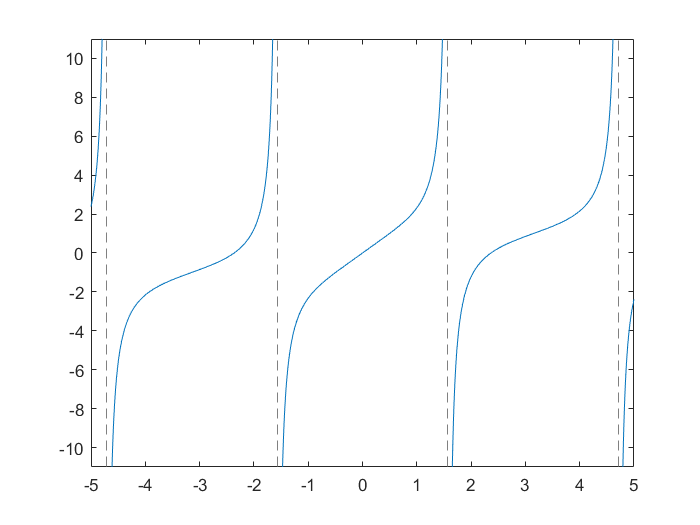

syms x;

y = tan(x) + tanh(x); 
fplot(y)

problem 2

syms t;
x = t^3 / 3 + cos(t/4) - t / 2;
x_d = diff(x);
gt(t) = 0.5*sqrt(sin(t/4)+2);
a = 0;
b = 1;
t0 = (a + b) / 2;
N = 50;
for i = 1 : N
    t0 = eval(gt(t0));
end
fprintf('\nRoot is: %f\n', t0);


Root is: 0.738862


problem 3

syms x 
a = 4*pi*8.9*10^9 * 2/(4*10^5*2*10^5);
f(x) = x - a*(sqrt(x^2+1/25))^3;
x0 = 0.5;
x1 = 1;
N = 8;
for i = 1:N
    fxn1 = x1 - (eval(f(x1))*(x1 - x0))/(eval(f(x1)) - eval(f(x0)));
    x0 = x1;
    x1 = fxn1;
end
fprintf('\nRoot is: %f\n', x1);


Root is: 0.543752
